# Analisi progetti IOT rispetto al settore 

tProgetto = readtable('progetti_setaccio_IOT.xlsx');
tSoggetti = readtable('soggetti_setacciato_IOT.xlsx');
% trasformo in categorical array per lavorarci su 
tProgetto.CUP_DESCR_SETTORE = categorical(tProgetto.CUP_DESCR_SETTORE);


Valutiamo il numero dei progetti per settore. Il settore con più progetti sull'IOT è RICERCA, SVILUPPO TECNOLOGICO ED INNOVAZIONE con un totale di 1540 progetti. 

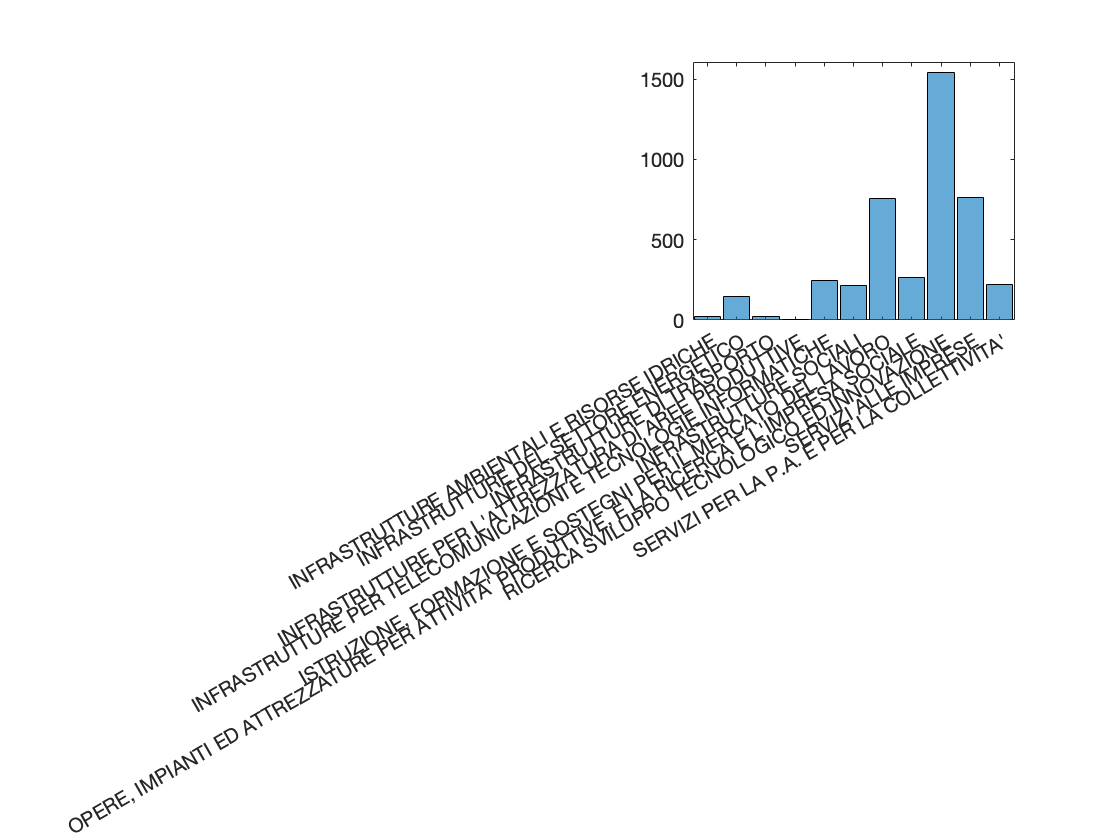

% quanti progetti per settore? 
histogram(tProgetto.CUP_DESCR_SETTORE);

Valutiamo adesso i primi 10 progetti più finanziati a quali settori appartengono.

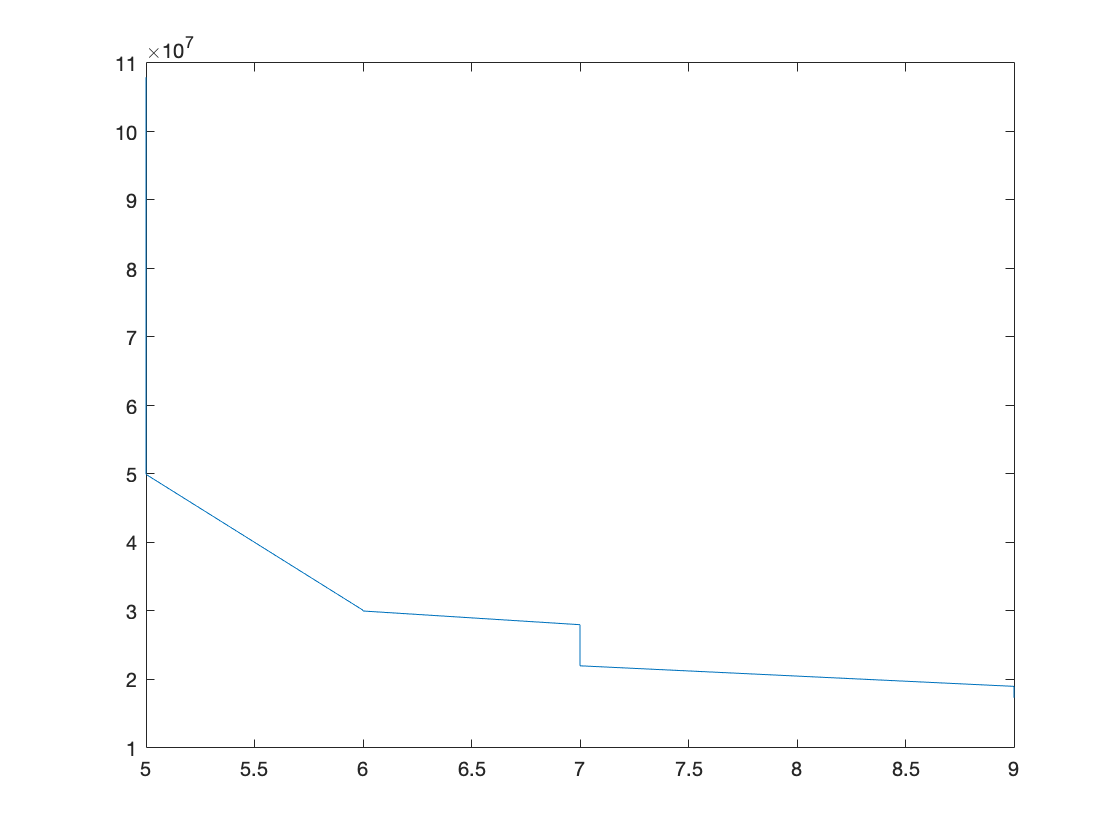

tProgetto = sortrows(tProgetto,'CUP_COD_SETTORE','ascend');
codSettore = tProgetto.CUP_COD_SETTORE;
finanze = tProgetto.FINANZ_TOTALE_PUBBLICO;

% valutiamo i N settori più finanziati 
N = 10; % abbiamo visto che dopo i primi 50 più finanziati gli altri 
        % sono più o meno sullo stesso livello
codSettoreN = zeros(N,1);
finanzeN = zeros(N,1);

for i=1:N
    [finanzeN(i), posizione] = max(finanze);
    codSettoreN(i) = codSettore(posizione);
    finanze(posizione) = [];
end
codSettoreN = sortrows(codSettoreN,'ascend');
finanze = tProgetto.FINANZ_TOTALE_PUBBLICO;
% grafica dei N settore più finanziati 
figure
plot(codSettoreN,finanzeN)

Valutiamo adesso la distrubuzione dei finanziamenti per settore andando a vedere qual è il settore che ha avuto il maggior numero di finanziamenti pubblici 

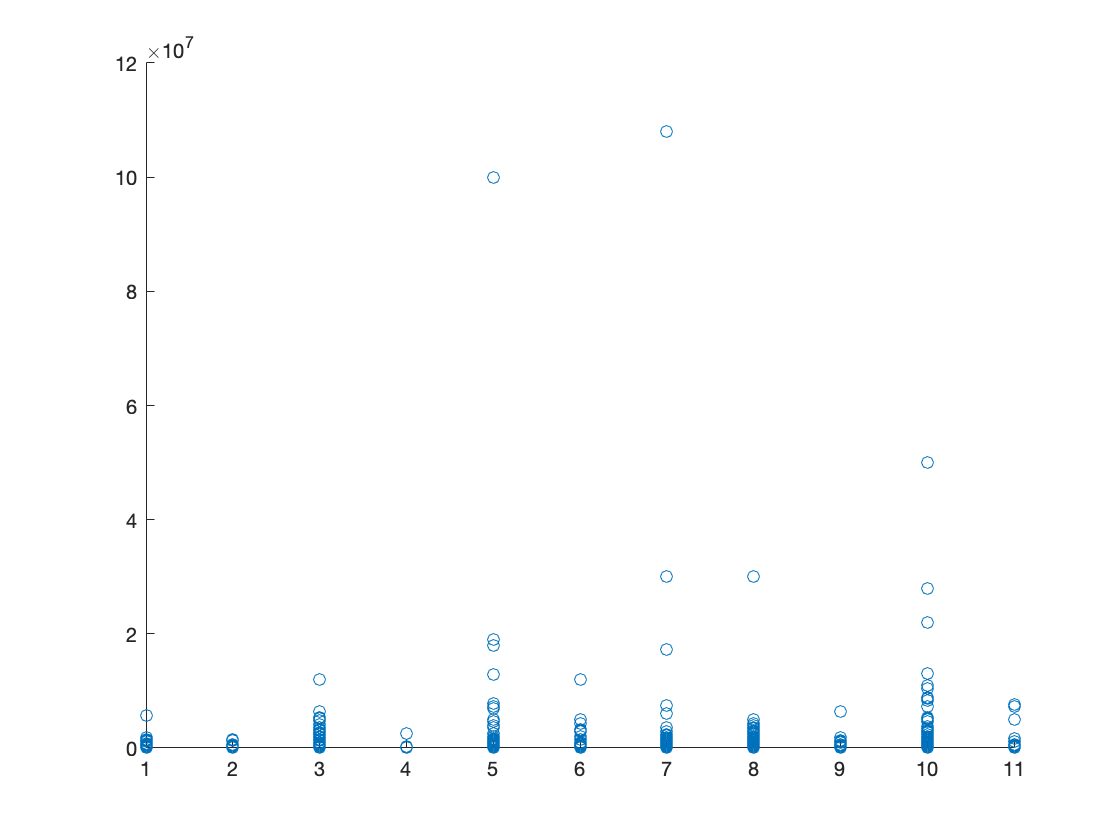

scatter(codSettore,finanze)